# Auto-generated by Image Acquisition Explorer

This script does the M-sqaured Test. Ezperiment conduct to test the beam qualitty.

## Device Setup

disp('--- System Information ---');

--- System Information ---


hwinfo = imaqhwinfo();
disp('Available Image Acquisition Adaptors:');

Available Image Acquisition Adaptors:


disp(hwinfo.InstalledAdaptors);

    {'gentl'}    {'gige'}




info_gentl = imaqhwinfo('gentl'); % Store the info in a variable first
disp(info_gentl.DeviceInfo)

  1×2 struct array with fields:

    DefaultFormat
    DeviceFileSupported
    DeviceName
    DeviceID
    VideoInputConstructor
    VideoDeviceConstructor
    SupportedFormats



## Define Camera Paramters

adaptorName = 'gentl';
deviceID = 2; % Blakfly was detected as 2 here
videoFormat = 'Mono8'

videoFormat = 'Mono8'

## Configure Camera

v=videoinput(adaptorName,deviceID,videoFormat);

src = getselectedsource(v);
src.ExposureAuto='Off'

src =    Display Summary for Video Source Object:

      General Settings:
        Parent = [1x1 videoinput]
        Selected = on
        SourceName = 0
        Tag = [0x0 string]
        Type = videosource

      Device Specific Properties:
        AasRoiEnable = False
        AasRoiHeight = (Currently not accessible)
        AasRoiOffsetX = (Currently not accessible)
        AasRoiOffsetY = (Currently not accessible)
        AasRoiWidth = (Currently not accessible)
        AcquisitionBurstFrameCount = 1
        AcquisitionFrameCount = 2
        AcquisitionFrameRate = 226.4431
        AcquisitionFrameRateEnable = False
        AcquisitionLineRate = 255427.8414
        AcquisitionResultingFrameRate = 226.4431
        AdcBitDepth = Bit10
        AutoAlgorithmSelector = Awb
        AutoExposureControlLoopDamping = 0.5
        AutoExposureControlPriority = (Currently not accessible)
        AutoExposureEVCompensation = 0
        AutoExposureExposureTimeLowerLimit = 100
        AutoExposu

src.ExposureTime = 540;
src.SequencerTriggerSource = "Off";

## Setting up ROI

v.ROIPosition = [0 0 1440 1080];

## Create Image Directory

fiberType = 'mutliMode_50um'; % Change this to the type of fiber being used.
Trial='No Magnets 1';
startImageIndex=1;
targetDir = fullfile(fiberType, Trial);
% --- Create the Directory if it Does Not Exist ---
[status, message, messageId] = mkdir(targetDir);

% Check if directory creation was successful
if status
    fprintf('Ensured directory exists: %s\n', targetDir);
else
    fprintf(2, 'Error creating directory %s: %s\n', targetDir, message);
    % return;
end

Ensured directory exists: mutliMode_50um\No Magnets 1


## Capture Image

Capture a single frame.

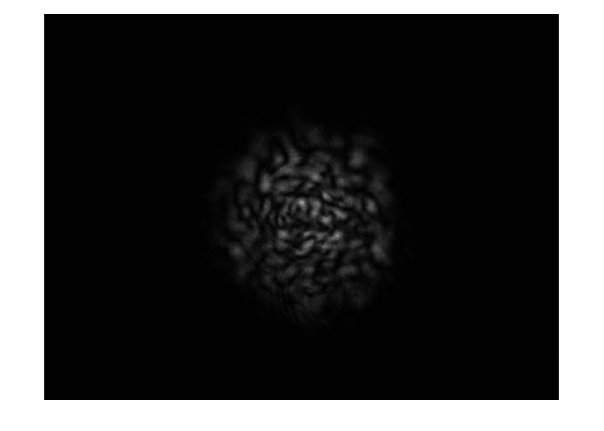

indexImages=30; % This will be manually updated for each image.
image=getsnapshot(v);
figure;
ax = axes();
maxIntensity = max(image(:));

if maxIntensity > 200
    fprintf('Max Intensity: %d, Check if image saturating\n',maxIntensity);
end
if maxIntensity < 100
    fprintf('Max Intensity: %d, Check if image dim\n',maxIntensity);
end
imshow(image,'DisplayRange',[0 256])

imageName=sprintf('image_%02d.png',indexImages);

## Save Images

Save each image

% --- Construct the Full File Path ---
fullFilePath = fullfile(targetDir, imageName);
% Save the image
imwrite(image, fullFilePath)

## M^2 Calculation